## Reading image

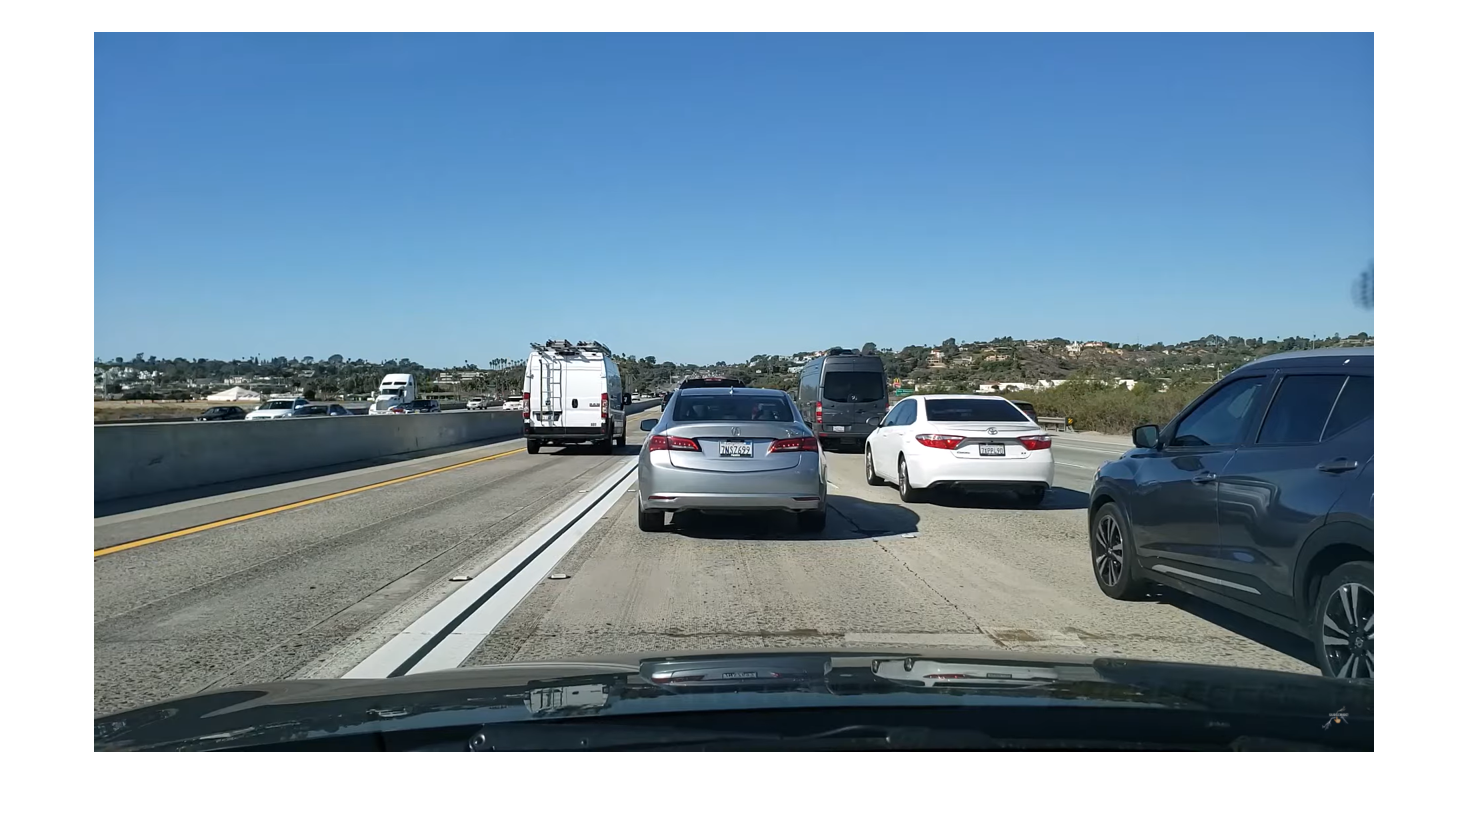

img = imread("test_imgs\test6.png");
hd_resolution = [720 1280];
img = imresize(img, hd_resolution);
imshow(img)

## Lane detection

leftLineOriginal = getLeftLineOnOriginalImage(img);
rightLineOriginal = getRightLineOnOriginalImage(img);
leftLineLong = spreadLineToLimits(leftLineOriginal, 450, 640);
rightLineLong = spreadLineToLimits(rightLineOriginal, 450, 625);

## Distance estimator

## Output image

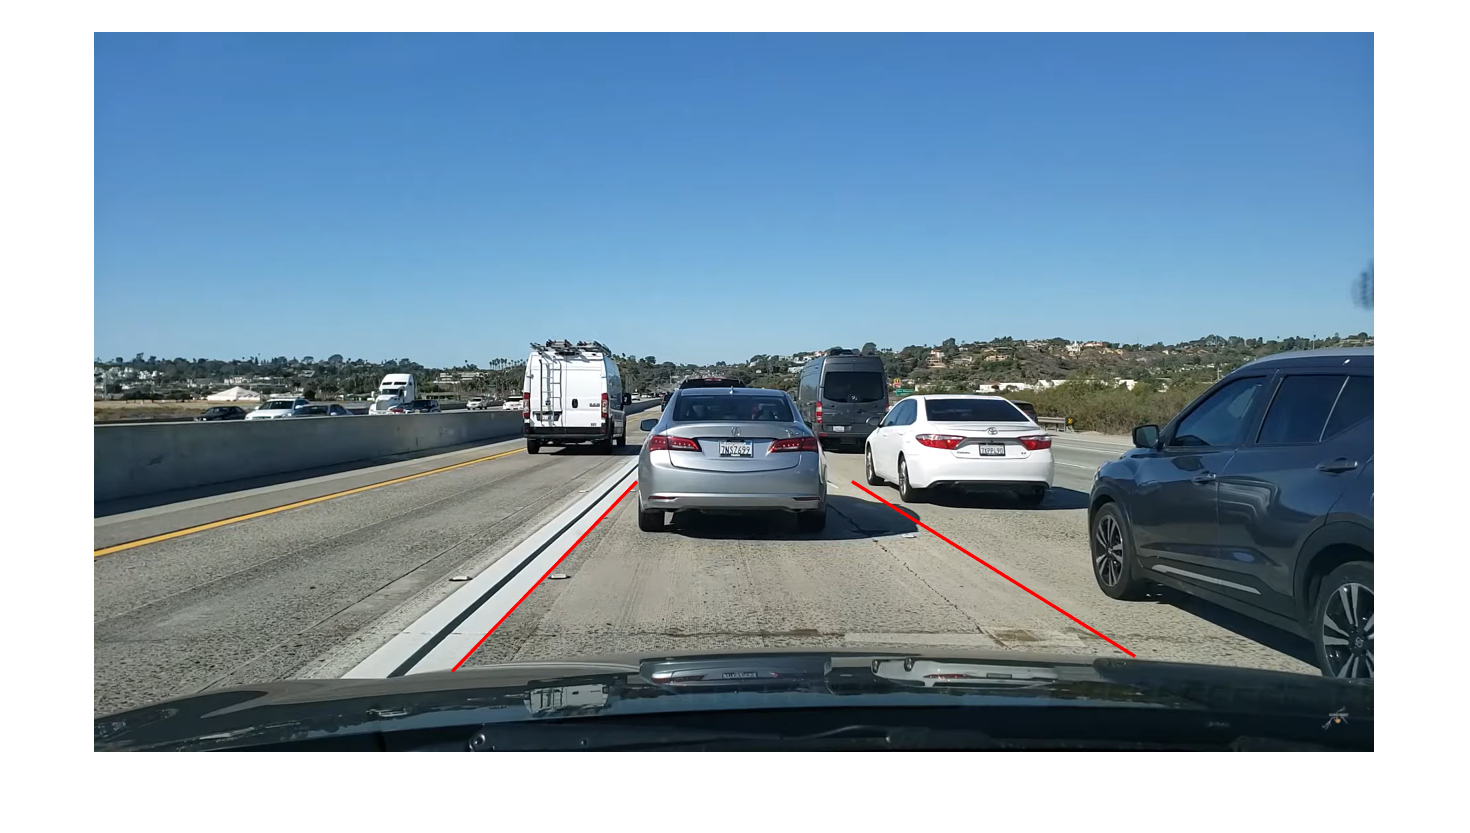

imshow(img)
hold on; plotLine(leftLineLong); hold off;
hold on; plotLine(rightLineLong); hold off;